# AMECH HW6

*Steven Henderson*

**1.**

**(c)**

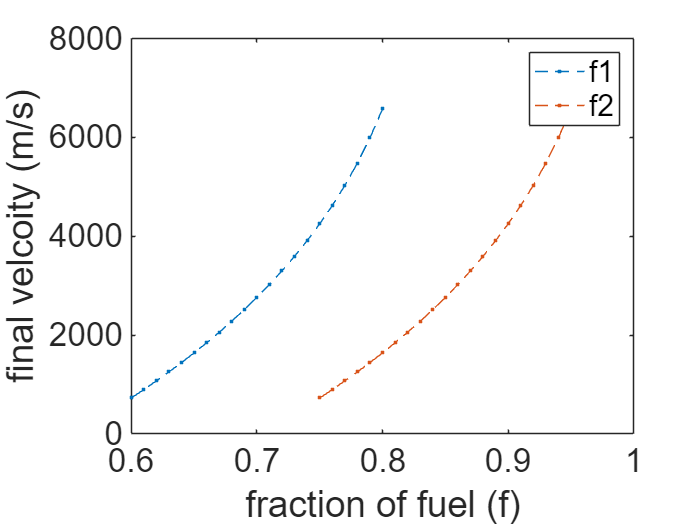

function v = find_v(T, u, mf, mi, vi)
    g = 9.8 ;
    v = - g * T - u * log(mf ./ mi) + vi ;
end
f = [0.6:0.01:0.8; 0.75:0.01:0.95] ;
u = 3000 ; 
T1 = 2.75 * 60 ;
T2 = 6.5 * 60 ;
m1 = 549 ;
m2 = 120 ;
mp = 0.375 ;
v1 = find_v(T1, u, m1 + m2 + mp - f(1, :).*m1, m1 + m2 + mp, 0) ;
v2 = find_v(T2, u, m2 + mp - m2.*f(2, :), m2 + mp, v1) ;
plot(f, v2, '--.')
set(gca, 'fontsize', 20)
xlabel('fraction of fuel (f)')
ylabel('final velcoity (m/s)')
legend('f1', 'f2')

**2.**

**(5)**

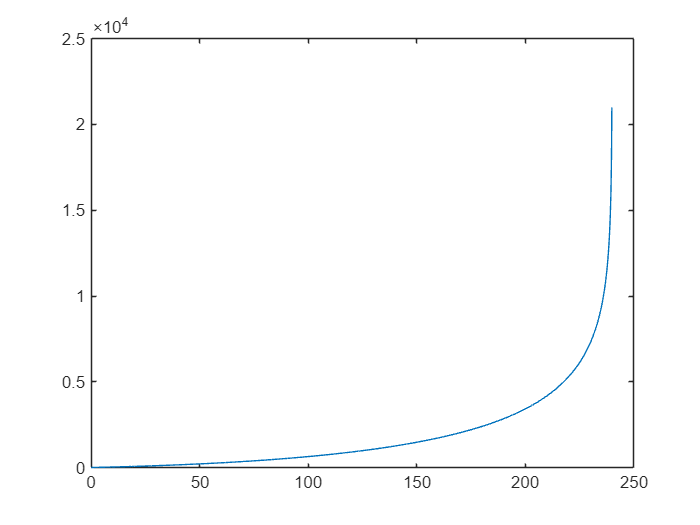

clear all
a = 1/4 ;
t = 0:0.1:4 *60;
u = 3000 ;
g = 9.8 ;
v = - u * log(1 - a.*(t / 60)) - g*t ;
h = 0 + v.*t - 1/2*g.*t.^2;
plot(t, v)

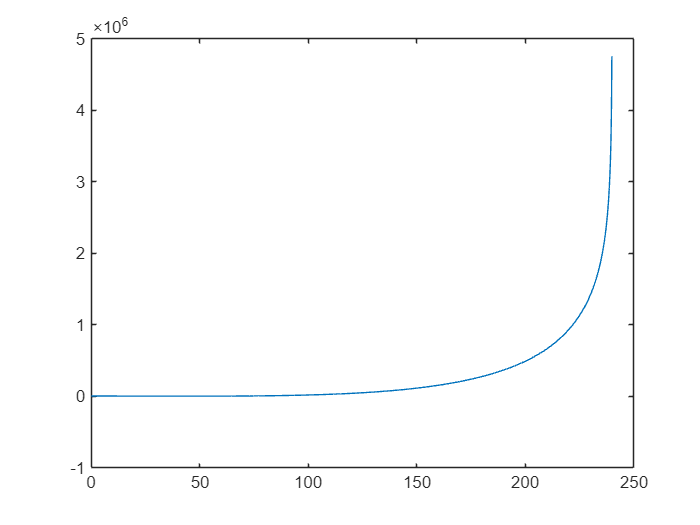

plot(t, h)

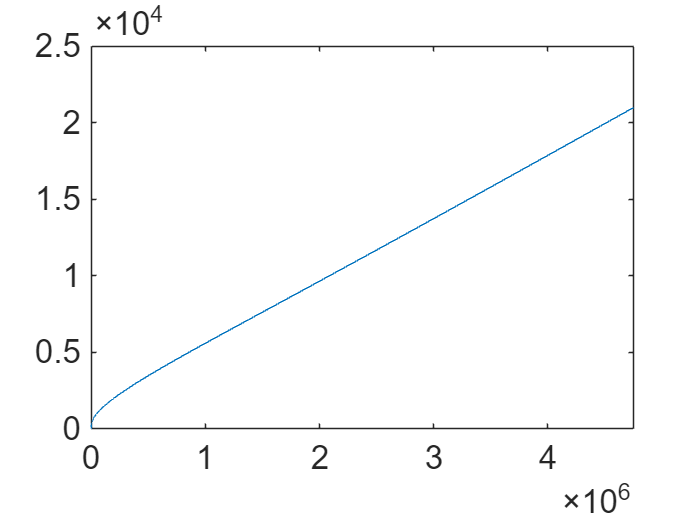

plot(h, v)
set(gca, 'fontsize', 20)